digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
'nndatasets','DigitDataset');

imds = imageDatastore(digitDatasetPath, ...
'IncludeSubfolders',true,'LabelSource','foldernames');

numTrainFiles = 10;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

tr_in = readall(imdsTrain);
tr_tg = imdsTrain.Labels;

ts_in = readall(imdsValidation);
ts_tg = imdsValidation.Labels;

omega_b = 0.2;
Nh = 784;
ts = 1000;
f = @(bias, hidden_weights, hidden) tanh(bias + hidden_weights*hidden);
x0 = zeros(Nh,1);
phi = @eulerForward;
eps = 0.001;
eigs = -10000*ones(Nh,1);
ws = 0;
lambda_r = 0.1;
%Nl = 1;
seed = 1;

addpath src

net = NeuralODE(omega_b, Nh, ts, f, phi, eps, eigs, ws, lambda_r, seed);

hidden = net.hiddenState(tr_in);

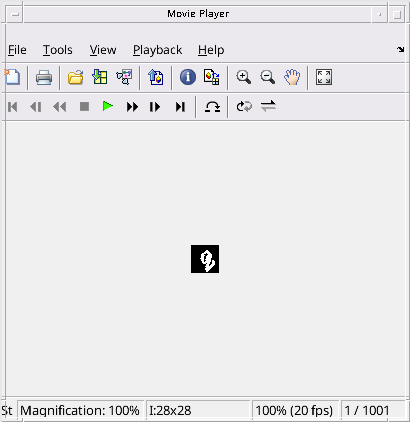

index_sample = 25;

hidden_sample = hidden{index_sample};
if Nh == 784 %Nh=Nu
    hidden_sample = reshape(hidden_sample,[28,28,size(hidden_sample,2)]);
    implay(hidden_sample)
end

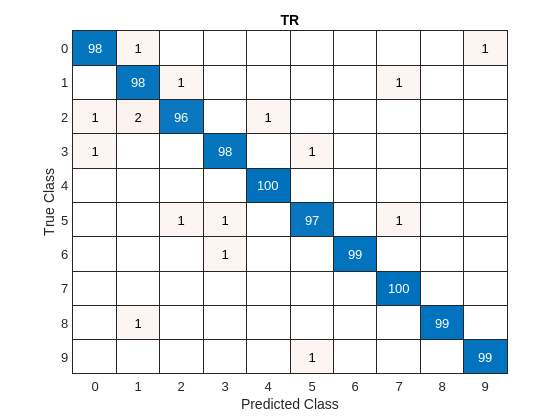

[net,pred_tr]=net.fit(tr_in,tr_tg);
figure
confusionchart(tr_tg, pred_tr);
title("TR")